IAE = 113.0379			P = 1		I = 0		D = 0
IAE = 264.8371			P = 11.998		I = 1.4633		D = 4.0723
IAE = 268.8792			P = 30.9112		I = 0.26994		D = 4.4557
IAE = 253.0019			P = 8.6402		I = 0.49686		D = 2.5522
IAE = 273.3824			P = 1.9722		I = 1.9528		D = 3.2904
IAE = 263.1772			P = 6.1378		I = 1.4077		D = 7.2356
IAE = 261.5745			P = 14.6113		I = 0.85518		D = 6.9307
IAE = 266.6578			P = 27.8918		I = 0.28762		D = 7.3803
IAE = 261.5266			P = 4.7287		I = 0.91708		D = 4.5099
IAE = 251.8225			P = 20.4696		I = 1.2005		D = 1.4906
IAE = 264.1073			P = 6.147		I = 1.5083		D = 5.4127
IAE = 266.4114			P = 25.4471		I = 0.37248		D = 2.8584
IAE = 252.6717			P = 22.2105		I = 1.6459		D = 1.4414
IAE = 268.2648			P = 24.548		I = 0.45769		D = 3.3077
IAE = 269.2125			P = 32.3771		I = 1.8118		D = 6.4077
IAE = 259.4148			P = 21.3734		I = 1.9071		D = 2.0103
IAE = 262.3997			P = 4.9408		I = 1.003		D = 5.3199
IAE = 258.2656			P = 27.4579		I = 0.66424		D = 1.4157
IAE = 270.6474			P = 32.9232		I = 0.38904		D = 3.4567
IAE = 80.4

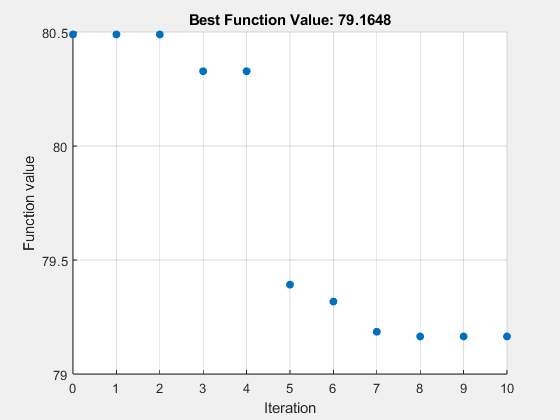

% Set nondefault solver options
options2 = optimoptions("particleswarm","InitialPoints",K_start,...
    "InertiaRange",Inertia_range,"SelfAdjustmentWeight",2,...
    "SocialAdjustmentWeight",2,"MaxIterations",10,"MaxStallIterations",5,...
    "Display","iter","PlotFcn","pswplotbestf");

% Solve
[sol,obj] = particleswarm(@tunning,numvar,lower_bounds,...
    upper_bounds,options2);


% Clear variables
clearvars options2